# 
$$\frac{\partial ^2 u}{\partial t^2} = a^2 \frac{\partial ^2 u}{\partial x^2}$$


Scenario: Modelling the perpendicular displacement $u\left(x,t\right)$ of a power transmission cable of length $L=1m$ over an arbitrary time interval from $t=0s$.

Boundary Conditions: The cable is fixed at both endpoints, initially at rest, and initially displaced to a position $u\left(x,0\right)=f\left(x\right)=\sin \left(\pi x\right)$.

Define key problem parameters

k = 0.1; % t-spacing Δt = k
h = 0.25; % x-spacing Δx = h
    % the chosen step sizes lead to a stable solution by the CFL stability condition
a = 1; % wave speed parameter in 1D Wave Equation
r = a*k/h; % Courant Number

xup = 1; tup = 0.5; % max x and t values in the numerical solution mesh space
xlow = 0; tlow = 0; % min x & t values in mesh space
x = xlow:h:xup; t = tlow:k:tup; % specific x and t values for which numerical solution u(x,t) is found

Plot of Mesh Points for the Numerical PDE Solution

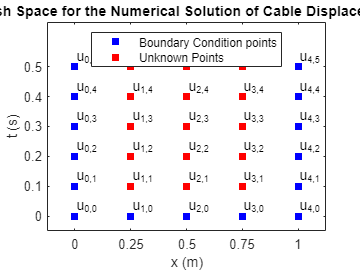

[X,T] = meshgrid(x, t); % set up mesh spaced by Δx Δt
bc = plot(X,T, 'bs', 'MarkerFaceColor','b'); % plot the meshgrid to visualise it
    %% bc for "boundary condition" - the blue points are given by bc's
hold on

unk = plot(X(2:end,2:end-1)', T(2:end,2:end-1)', 'rs', 'MarkerFaceColor','r');
    %% "unk" = unknowns - not given by bc's
hold off
%% plot all mesh points blue and then overwrite middle 15 mesh points as red
%% to show the red as the unknown points

yticks(t)
xticks(x) % set x and t ticks to step sizes Δx Δt

xlim([xlow - 0.5*h, xup + 0.5*h])
ylim([tlow - 0.5*k, tup + 1.5*k]) % x & t limits in the plot. Space on top for the legend

xlabel("x (m)")
ylabel("t (s)")
title("Mesh Space for the Numerical Solution of Cable Displacement")

legend([bc(1), unk(1)], "Boundary Condition points", "Unknown Points", ...
    "Location", "north")
    %% passing by 1st element of plot handles for boundary condition (blue)
    %% and unknown (red) points to set the correct colours in the legend entries

for i = 1:length(x)
    for j = 1:length(t)
        label = {"u_{" + num2str(i-1) + "," + num2str(j-1) + "}"};
            % i,j >= 1 due to indexing so (i,j - 1) in num2str to get numbers from 0.
            % alternate is num2str((i-1)*10 + (j-1)) but produces 0 at i=j=1, not 00
        text(X(1,i), T(j,1), label, ...
            'VerticalAlignment','bottom','HorizontalAlignment','left')
    end
end

Numerical Iterative Mesh Method for 1D Wave Equation

u_numerical = zeros(tup/k+1,xup/h+1); % solution matrix is a t by x matrix
    % ascending time goes by descending row: row 1 for t=0, row 2 for
    % t = k, row 3 for t = 2k, etc

% Boundary Conditions
    %bc_l = zeros(tup/k + 1, 1);
    %bc_r = bc_l;
    % --- could define these but simpler to just set u_numerical = 0 in 
    % recursive steps instead of u_numerical(i,j) = bc_l(j) or bc_r(j)

for i = 1:xup/h+1
    u_numerical(1, i) = sin(pi * (i-1) * h); % 1st row for t=0 by boundary condition
end

% 1st row (middle elements plus bc_l and bc_r elements = 0 given by bc):
for i = 1:xup/h+1
    if i == 1 || i == xup/h+1
        u_numerical(2,i) = 0; % 0 by boundary condition
    else
        u_numerical(2,i) = 0.5*(r^2)*u_numerical(1,i-1) + ...
        (1-(r^2))*u_numerical(1,i) + 0.5*(r^2)*u_numerical(1,i+1); % 2st row, t = k
        % recursive formula for t = k using bc "cable initially at rest"
    end
end

for j = 2:tup/k % iterate over t-steps to next row - start from row 3 till last row
    for i = 1:xup/h+1 % iterate over x-steps along the row
        if i == 1 || i == xup/h+1
            u_numerical(j+1,i) = 0;
        else 
            u_numerical(j+1,i) = (r^2)*u_numerical(j,i-1) + ...
            2*(1-(r^2))*u_numerical(j,i) + (r^2)*u_numerical(j,i+1) - ...
            u_numerical(j-1,i);
            % recursive formula to calculate the next row of meshpoints from prev 2 rows
        end
    end
end
disp(u_numerical); % see the u-values of the mesh points - numerical solution

         0    0.7071    1.0000    0.7071    0.0000
         0    0.6740    0.9531    0.6740         0
         0    0.5777    0.8169    0.5777         0
         0    0.4272    0.6042    0.4272         0
         0    0.2367    0.3348    0.2367         0
         0    0.0241    0.0340    0.0241         0



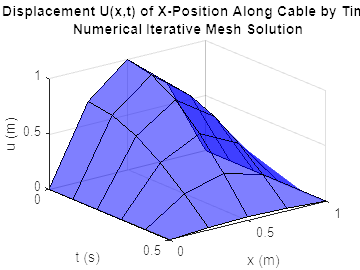


surf(x, t, u_numerical, 'FaceAlpha', 0.5, 'FaceColor', 'b')
set(gca, 'Ydir', 'reverse')
    % revese t direction to see the decreasing oscillation better
xlabel("x (m)")
ylabel("t (s)")
zlabel("u (m)")
title("Displacement U(x,t) of X-Position Along Cable by Time" + ...
    newline + "Numerical Iterative Mesh Solution")

Plot the Analytical Solution $u(x,t) = \sin{(\pi x)} \cos{(\pi t)}$ found from analytical Wave Equation solution

u_exact = sin(pi*X) .* cos(pi*T); % using meshgrid set up in Line 9)

disp(u_exact); % see exact u-values of mesh points

         0    0.7071    1.0000    0.7071    0.0000
         0    0.6725    0.9511    0.6725    0.0000
         0    0.5721    0.8090    0.5721    0.0000
         0    0.4156    0.5878    0.4156    0.0000
         0    0.2185    0.3090    0.2185    0.0000
         0    0.0000    0.0000    0.0000    0.0000



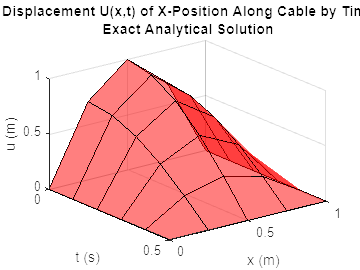


surf(X,T,u_exact, 'FaceAlpha', 0.5, 'FaceColor', 'r')
set(gca, 'Ydir', 'reverse') % reverse to see cable displacement better
% x & t sizes are incompatible so cannot use "uexact = sin(pi*x).*cos(pi*t)"
xlabel("x (m)")
ylabel("t (s)")
zlabel("u (m)")
title("Displacement U(x,t) of X-Position Along Cable by Time" + ...
    newline + "Exact Analytical Solution")

Calculate % error of each numerical mesh computation from analytical result

error = (u_numerical - u_exact);

percerror = zeros(size(error)); % percent error array
for j = 1:length(t)
    for i = 2:length(x)-1
        percerror(j,i) = 0;
        if mod((j-1)*k, 0.5) == 0
            percerror(j,i) = 0; % undefined error as exact solution = 0 at t = n/2 for int n >= 1
            continue % skip rest of calculation to avoid division by 0
        else
            percerror(j,i) = error(j,i)/u_exact(j,i) * 100;
        end
    end
end

disp(percerror);

         0         0         0         0         0
         0    0.2188    0.2188    0.2188         0
         0    0.9794    0.9794    0.9794         0
         0    2.7885    2.7885    2.7885         0
         0    8.3383    8.3383    8.3383         0
         0         0         0         0         0



percerror = abs(percerror); % to display on bar graph

%percerrormid = error(1:tup/k,2:xup/h)./u_exact(1:tup/k,2:xup/h) * 100;
%percerror = vertcat(percerrormid, [NaN, NaN, NaN])

b = bar(percerror(:,2)); %1st col = 0 from boundary condition. 2nd to (end-1) cols are equal
xlabel("Iteration in Time")
ylabel("Percent Error")
title("Error in Numerical Solution from Analytical")

if length(b.XData) <= 15 % with 16+ bars, bars cannot fit numbers on top - too much number clatter
    for i = 1:length(b)
        text(b(i).XData, b(i).YData, num2str(percerror(:,2), '%.01f'), ...
            'VerticalAlignment','bottom','horizontalalign','center');
    end
end
ylim([0 1.2*max(b.YData)]) % plot goes till 1% above max percent error